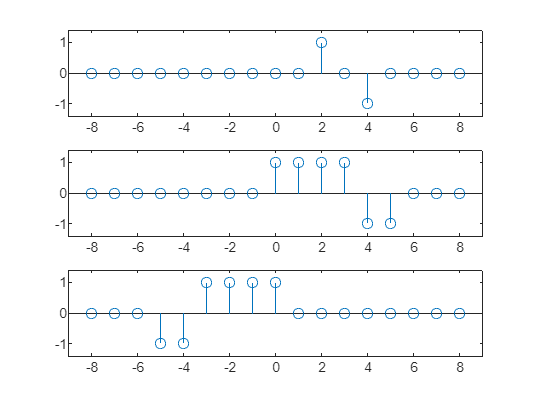

% x[n]: Signal given for Question 7
% h[n]: Impluse response of x[n]

n = -8:8;
h = zeros(length(n), 1);
h(0 <= n & n <= 3) = 1;
h(4 <= n & n <= 5) = -1;
x = zeros(length(n), 1);
x(n == 2) = 1;
x(n == 4) = -1;
h_in = zeros(length(n), 1);
h_in(0 <= -n & -n <= 3) = 1;
h_in(4 <= -n & -n <= 5) = -1;

subplot(3, 1, 1);
stem(n, x);
ylim([-1.4, 1.4]);
xlim([min(n)-1, max(n)+1]);

subplot(3, 1, 2);
stem(n, h);
ylim([-1.4, 1.4]);
xlim([min(n)-1, max(n)+1]);

subplot(3, 1, 3);
stem(n, h_in);
ylim([-1.4, 1.4]);
xlim([min(n)-1, max(n)+1]);

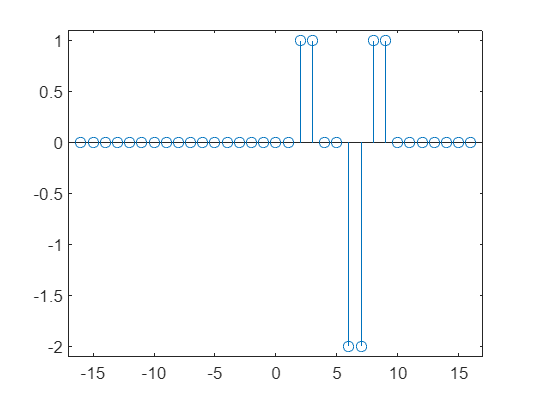

N = -(length(n)-1):length(n)-1;
y = conv(x, h);
subplot(1, 1, 1);
stem(N, y);
ylim([-2.1, 1.1]);
xlim([min(N)-1, max(N)+1]);